Práctica 6: implementación de filtros LTI utilizando DFT  

Carga inicial de parámetros

clear; close all; clc;

% Cargar parámetros del filtro especificados en el archivo .mat
if exist('PDS_P6_3A_LE2_G4.mat', 'file')
    load('PDS_P6_3A_LE2_G4.mat');
    fprintf('Parámetros cargados:\n');
    fprintf('  M = %d (orden del filtro)\n', M);
    fprintf('  Apass = %.1f dB (atenuación en banda de paso)\n', Apass);
    fprintf('  Astop = %.1f dB (atenuación en banda de rechazo)\n', Astop);
else
    error('El archivo PDS_P6_3A_LE2_G4.mat no se encuentra en la carpeta actual.');
end

Parámetros cargados:


  M = 100 (orden del filtro)


  Apass = 0.1 dB (atenuación en banda de paso)


  Astop = 80.0 dB (atenuación en banda de rechazo)


Diseño de un filtro FIR  

a) Lectura y reproducción de la señal de audio

load("PDS_P6_3A_LE2_G4.mat");
% Lectura del archivo de audio
[x, fs] = audioread('PDS_P6_3A_LE2_G4.wav');

% Reproducción del audio (comenzar con volumen bajo)
sound(x, fs);

b) Especificación de la frecuencia de muestreo y frecuencia de corte

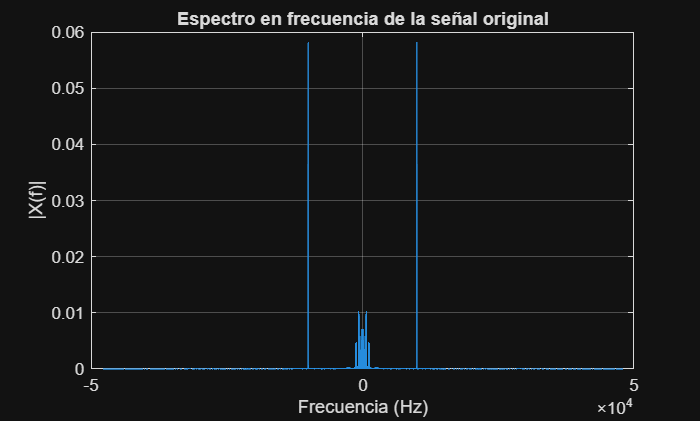

%% Obtención y representación 
N = length(x);

% FFT normalizada
X = fft(x) / N;

% Eje de frecuencias centrado
f = linspace(-fs/2, fs/2, N);

% Espectro centrado
X_shift = fftshift(abs(X));

figure;
plot(f, fftshift(abs(X)));
grid on;
xlabel('Frecuencia (Hz)');
ylabel('|X(f)|');
title('Espectro en frecuencia de la señal original');


%% Obtencion componentes espectrales de mayor frec
% Umbral para detectar picos relevantes (10% del máximo)
threshold = 0.1 * max(X_shift);

% Índices de componentes relevantes
idx = find(X_shift > threshold);

% Frecuencias correspondientes
freqs_relevantes = f(idx);

% Componente positiva de mayor frecuencia
f_pos_max = max(freqs_relevantes(freqs_relevantes > 0));

% Componente negativa de mayor frecuencia
f_neg_max = min(freqs_relevantes(freqs_relevantes < 0));

% Mostrar resultados
disp(['Componente frecuencial positiva más alta: ', num2str(f_pos_max), ' Hz']);

Componente frecuencial positiva más alta: 10001.034 Hz


disp(['Componente frecuencial negativa más alta: ', num2str(f_neg_max), ' Hz']);

Componente frecuencial negativa más alta: -10000.8298 Hz


c) Diseño del filtro FIR con fdatool

load("filtro_fir.mat");

d) Representación de la respuesta en frecuencia del filtro

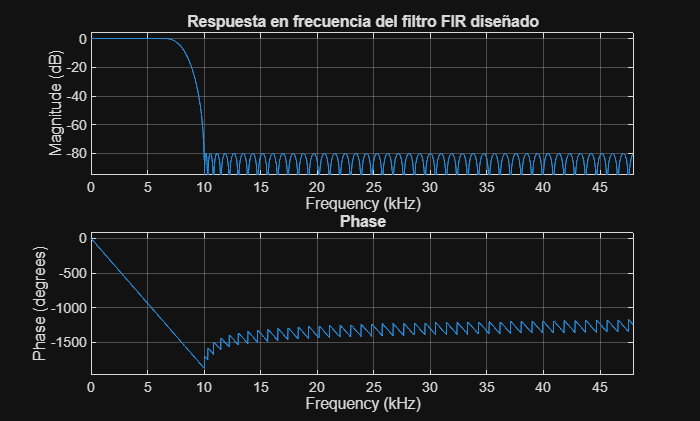

figure;
freqz(b, 1, 2048, fs);
grid on;
title('Respuesta en frecuencia del filtro FIR diseñado');

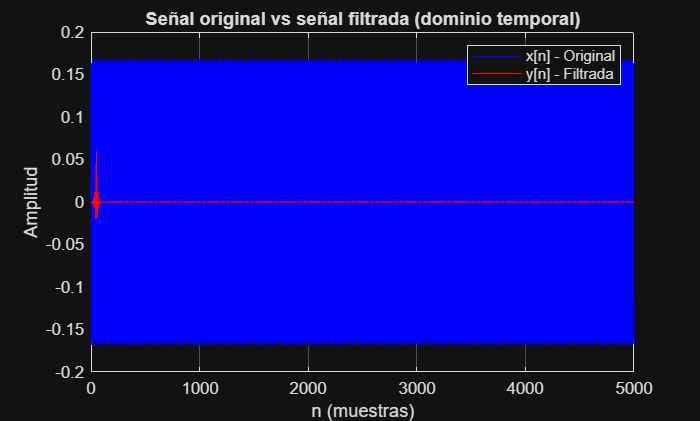

% Filtrado de la señal
y = filter(b, 1, x);

% Reproducir señal filtrada (opcional)
sound(y, fs);

% Número de muestras a visualizar
Ns = 5000;
n = 0:Ns-1;

figure;
plot(n, x(1:Ns), 'b');
hold on;
plot(n, y(1:Ns), 'r');
grid on;

xlabel('n (muestras)');
ylabel('Amplitud');
title('Señal original vs señal filtrada (dominio temporal)');
legend('x[n] - Original', 'y[n] - Filtrada');

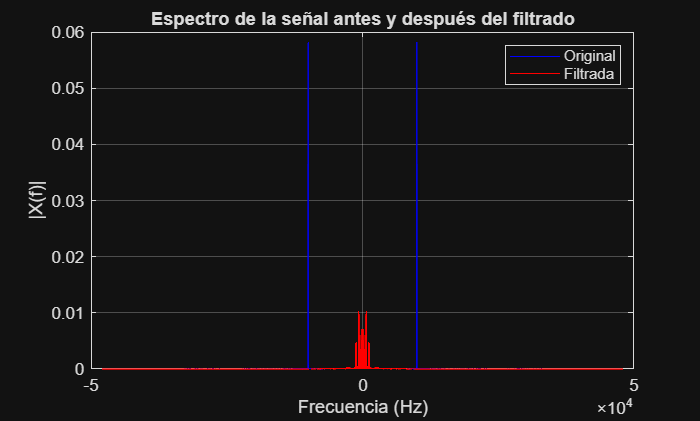



% FFT de ambas señales
X = fft(x) / N;
Y = fft(y) / N;

% Eje de frecuencias
f = linspace(-fs/2, fs/2, N);

% Espectros centrados
X_shift = fftshift(abs(X));
Y_shift = fftshift(abs(Y));

figure;
plot(f, X_shift, 'b');
hold on;
plot(f, Y_shift, 'r');
grid on;

xlabel('Frecuencia (Hz)');
ylabel('|X(f)|');
title('Espectro de la señal antes y después del filtrado');
legend('Original', 'Filtrada');

Implementación de un filtro FIR utilizando DFT  

a) Implementación del algoritmo de solape-almacenamiento

% Normalizar la señal de entrada (rango [-1, 1])
x_n = x / max(abs(x));

% Longitud del filtro FIR
P = length(b);

% Longitud del segmento de procesamiento
L = 500; % Procesamos 500 muestras a la vez

% Número de trozos/segmentos a procesar
num_trozos = floor(length(x_n) / (L - (P - 1)));

% Crear padding: agregar ceros al final para que sea exacto
num_ceros = num_trozos * (L - (P - 1));
x_n_pad = [x_n; zeros(num_ceros - length(x_n), 1)];

% Inicializar vector de salida
y_n = zeros(num_trozos * (L - (P - 1)), 1);

b) Código comentado del algoritmo

% Rellenar el filtro con ceros hasta longitud L (zero-padding)
h_n = [b'; zeros(L - P, 1)];

% FFT del filtro (se calcula una sola vez, reutilizable)
H_n = fft(h_n, length(h_n));

%% INFORMACIÓN DE PARÁMETROS

fprintf('===== PARÁMETROS CALCULADOS =====\n');
fprintf('Longitud del filtro (P): %d\n', P);
fprintf('Longitud de segmento (L): %d\n', L);
fprintf('Número de segmentos (num_trozos): %d\n', num_trozos);
fprintf('Muestras útiles por segmento: %d\n', L - (P - 1));
fprintf('Longitud de x_n_pad: %d\n', length(x_n_pad));
fprintf('Longitud de y_n inicializada: %d\n', length(y_n));

===== PARÁMETROS CALCULADOS =====


c) Justificación del parámetro P

% Parámetro P (longitud de la DFT)

Longitud del filtro (P): 101


P = L + length(b) - 1;

Longitud de segmento (L): 500


Número de segmentos (num_trozos): 1175


fprintf('\n=== PARÁMETRO P (Longitud de la DFT) ===\n');

Muestras útiles por segmento: 400


fprintf('L (longitud del segmento de entrada) = %d muestras\n', L);

Longitud de x_n_pad: 470002


fprintf('M (orden del filtro) = length(b) = %d\n', length(b));

Longitud de y_n inicializada: 470000


fprintf('P = L + M - 1 = %d + %d - 1 = %d\n\n', L, length(b), P);

Análisis de resultados

a) Aplicación del filtro con la función `filter` de Matlab

g = filter(b,1,x_n);

b) Comparación temporal: y(t) vs g(t)

n = 0:length(y)-1;


=== PARÁMETRO P (Longitud de la DFT) ===


L (longitud del segmento de entrada) = 500 muestras


figure;

M (orden del filtro) = length(b) = 101


plot(n, y, 'b', 'LineWidth', 1.2); hold on;

P = L + M - 1 = 500 + 101 - 1 = 600



plot(n, g, 'r--', 'LineWidth', 1.2);
grid on;
legend('y[n]', 'g[n]');
xlabel('n');
ylabel('Amplitud');
title('Comparación temporal entre y[n] y g[n]');

c) Error cuadrático medio (MSE) entre y[n] y g[n]

% Asegurar misma longitud
N = min(length(y), length(g));

% Calcular el ECM
ECM = mean((y(1:N) - g(1:N)).^2);

% Mostrar el resultado
fprintf('El error cuadrático medio entre y[n] y g[n] es: %.6f\n', ECM);

d) Comparación del espectro en frecuencia: x[n], y[n] y g[n]

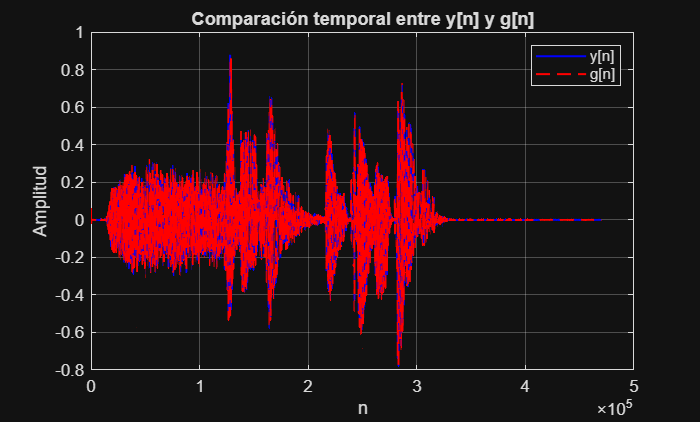

% Longitud FFT
Nfft = max([length(x), length(y), length(g)]);
Nfft = 2^nextpow2(Nfft);


% FFT centrada (correcta)
X = fftshift(fft(x, Nfft));
Y = fftshift(fft(y, Nfft));
G = fftshift(fft(g, Nfft));

% Eje de frecuencia normalizada (-0.5 a 0.5)
f = linspace(-0.5, 0.5, Nfft);

% Magnitud

El error cuadrático medio entre y[n] y g[n] es: 0.000000


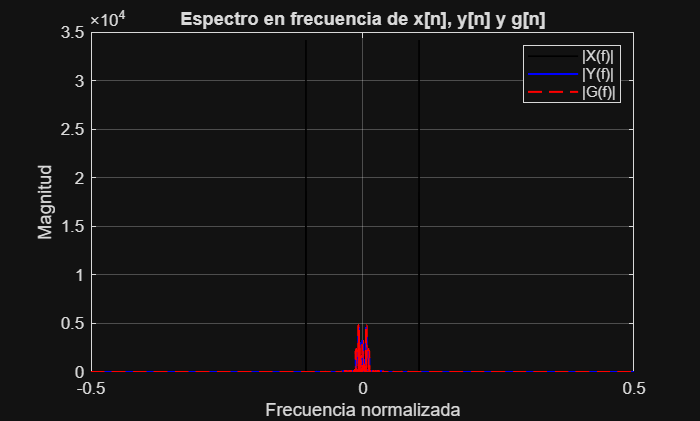

Xmag = abs(X);
Ymag = abs(Y);
Gmag = abs(G);

% Representación
figure;
plot(f, Xmag, 'k', 'LineWidth', 1); hold on;
plot(f, Ymag, 'b', 'LineWidth', 1.2);
plot(f, Gmag, 'r--', 'LineWidth', 1.2);
grid on;
legend('|X(f)|', '|Y(f)|', '|G(f)|');
xlabel('Frecuencia normalizada');
ylabel('Magnitud');
title('Espectro en frecuencia de x[n], y[n] y g[n]');
xlim([-0.5 0.5]);

e) Conclusiones y análisis de resultados

Hemos podido comprobar que se ha podido fitlrar con la DFT y con el algoritmo de solape-almacenamiento, consiguiendo un ECM nulo. Ello demuestra que mediante la igualación de la convolución circular y linear (con el uso de DFTs, que normalmente no es equivalente), se logra un resultado equivalente y óptimo al del uso de un filtro FIR.